# A tutorial on the refined Efficient Global Optimisation algorithm

Please cite [1-3] when using this software for your work or research, Thank you. 

This tutorial is the MATLAB code for "A global-local meta-modelling technique for model updating" article [1].

## The Test Functions

The first test function is a modified version of the Branin function [4] with an output scaled between 0 and 1 and two input variables. This function has two local minima and its contour plot is shown in Fig. 1.

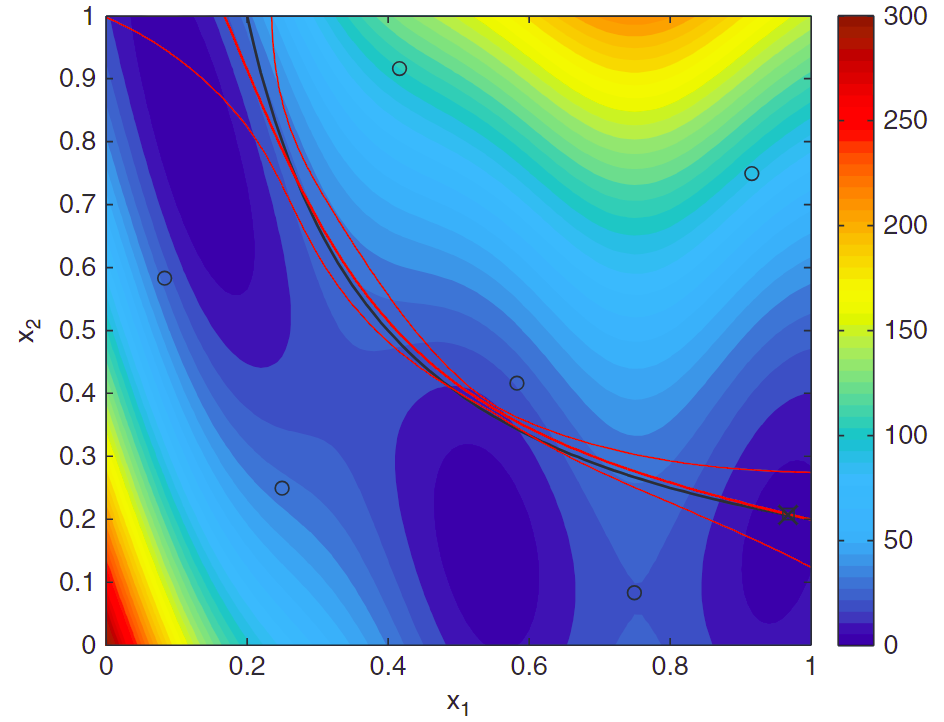

The second test function is the three storey structure from the EI at LANL [5], the same as in [1]. Fig. 2 shows the system schematic and Fig. 3 the equivalent mass-spring-damper system.

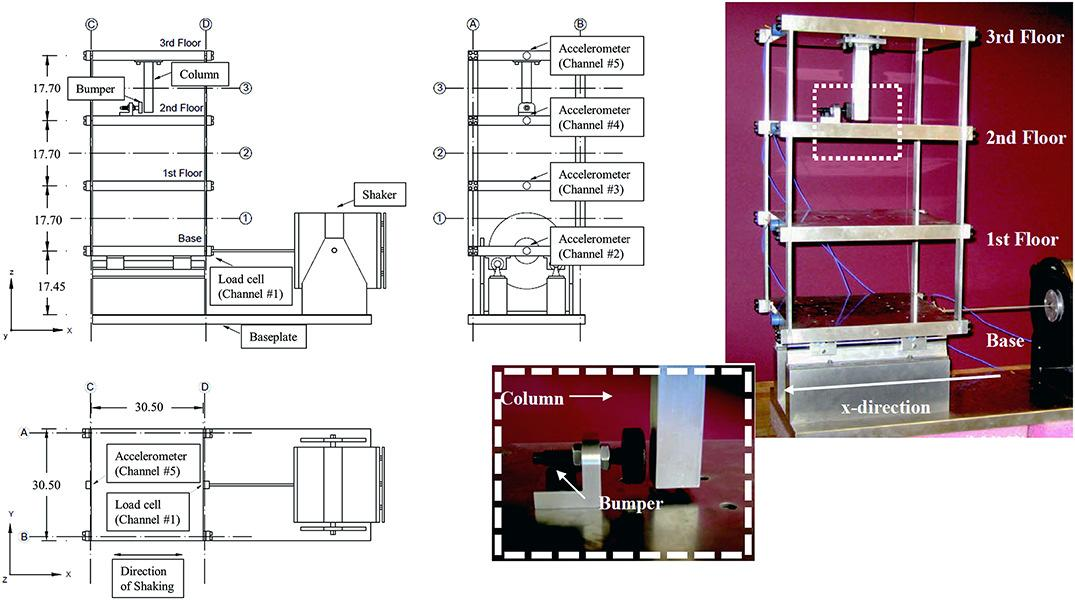

Fig. 2 Three storey structure schamatic and photos (Adapted from [5]).

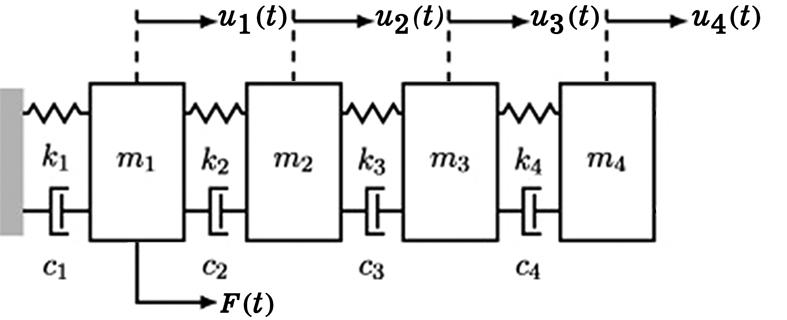

Fig. 3 Equivalent Mass spring damper system.

For the sake of this tutorial, a reduction in stiffness of 25% in the second interstory (${\mathit{\mathbf{k}}}_3$) is considered. Please note, only the three stiffness values of the interstories (${\mathit{\mathbf{k}}}_{2-4}$) are updated in this tutorial. The difference in the modal parameters between the two systems, quantified as the modified total modal assurance criterion (MTMAC), is to be minimised to characterise the change in stiffness. The numerical model developed in [1] is used for this task.

## The Modified Branin Function

In this section the Modified Branin Function is minimised using the rEGO.

 iteration: 0, evaluation: 20, current best solution: 0.004209, real optimum: 0.000000
EI: 0.017693
 iteration: 1, evaluation: 21, current best solution: 0.004209, real optimum: 0.000000
Stall iterations 1
EI: 0.024865
 iteration: 2, evaluation: 22, current best solution: 0.004209, real optimum: 0.000000
Stall iterations 2
EI: 0.035834
 iteration: 3, evaluation: 23, current best solution: 0.004209, real optimum: 0.000000
Stall iterations 3
EI: 0.012029
 iteration: 4, evaluation: 24, current best solution: 0.004209, real optimum: 0.000000
Stall iterations 4
EI: 0.0042808
 iteration: 5, evaluation: 25, current best solution: 0.004209, real optimum: 0.000000
Stall iterations 5
EI: 0.0034022
 iteration: 6, evaluation: 26, current best solution: 0.001465, real optimum: 0.000000
EI: 0.00083229
 iteration: 7, evaluation: 27, current best solution: 0.001465, real optimum: 0.000000
 iteration: 7, evaluation: 28, current best solution: 0.000003, difference: 0.000742
, samples: 28.000000
Refineme

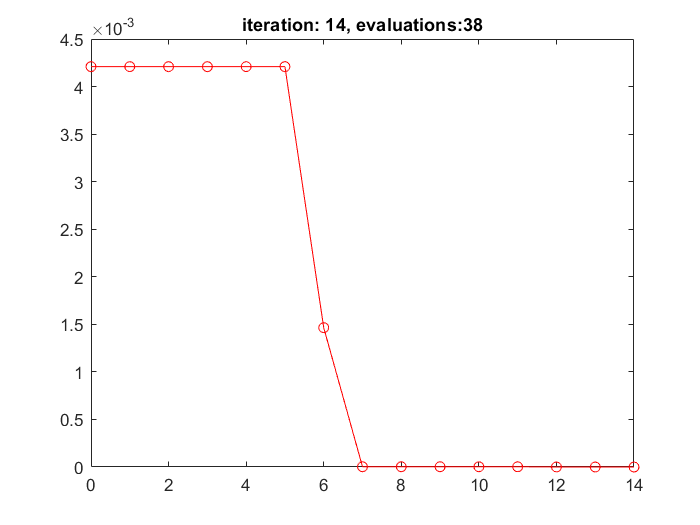

 iteration: 14, evaluation: 38, current best solution: 0.000000, real optimum: 0.000000
 iteration: 14, evaluation: 39, current best solution: 0.000000, difference: 0.000000
, samples: 18.000000
Refinement:1
Distance is 4.5761e-05


x =     0.1216    0.8239


fval = 2.0721e-09

results = struct with fields:
       initial: [20×3 double]
         min_x: [15×2 double]
         min_y: [0.0042 0.0042 0.0042 0.0042 0.0042 0.0042 0.0015 2.6858e-06 2.6858e-06 2.6858e-06 2.6858e-06 2.6858e-06 3.0173e-07 2.5519e-08 2.0721e-09]
       samples: [20 21 22 23 24 25 26 7 8 9 10 12 14 16]
             x: [18×2 double]
             y: [18×1 double]
    evaluation: 39
          fval: 2.0721e-09
     iteration: 14
            EI: 0
          diff: 4.5761e-05
          flag: 0
    refinement: 1
         stall: 0


%% Preamble
close all
clear all
dd = split(fileparts(matlab.desktop.editor.getActiveFilename),'\Tutorial');
cd(dd{1}) %set working directory to main folder
addpath(genpath(dd{1})) % add paths to matlab only for this session
clear dd

%%-------------------------------------------------------------------------------------

fun = @(x)braninmodif_n(x); % assign Branin function
num_vari = 2; % call number of variables
lwb = [0 0]; upb = [1 1]; % search bounds
eps1 = 10^(-3); eps2 = 10^(-4); % stopping criterion 

[x,fval,results] = rEGO(fun,num_vari,lwb,upb,eps1,eps2)

## The Three Storey Structure

In this section the rEGO is used to identify the damage in a simulated structure by minimising the MTMAC between the damaged and update system. Damage is simulated with a 25% decrease in ${\mathit{\mathbf{k}}}_3$.

Let us load the dataset for the damaged mode and show the modal parameters of the damaged and baseline model:

clear all
load LANL_3SS_dam_25_3.mat % load damaged modal parameters
load LANL_3SS.mat % load baseline modal parameters

Modal properties of the baseline system:

baseline(:,2:end) 

ans =    30.6968   54.2099   70.7509
    0.0600    0.0200    0.0080
   -1.0000   -1.0000   -0.4826
   -0.4217    0.8100    1.0000
    0.3287    0.8409   -0.9198
    0.8703   -0.8873    0.3989


Modal properties of the damaged system:

damaged(:,2:end)

ans =    29.3673   50.2963   69.0295
    0.0600    0.0200    0.0080
   -0.9898   -1.0000   -0.5197
   -0.4659    0.5581    1.0000
    0.2406    0.9927   -0.7345
    1.0000   -0.8035    0.2298


Difference, in percentage, between damaged and baseline natural frequencies:

delta_w = 100.*(damaged(1,2:end)-baseline(1,2:end))./baseline(1,2:end)

delta_w =    -4.3313   -7.2192   -2.4331


Diagonal of the MAC matrix of the damaged and baseline mode shapes:

mac = diag(compute_mac(damaged(2:end,2:end),baseline(2:end,2:end)))'

mac =     0.9900    0.9707    0.9771



$$\text{MTMAC}_{residuals}=1-\prod^n_{i=1}\frac{\text{MAC}(\bf{\phi}_i^E,\bf{\phi}_i^N)}{\Bigg(1+\frac{|\omega_i^N-\omega_i^E|}{|\omega_i^N+\omega_i^E|}\Bigg)}$$


yt = mac.*((1+abs((damaged(1,2:end)-baseline(1,2:end))./(damaged(1,2:end)+baseline(1,2:end)))).^(-1));
mtmac=1-prod(yt)

mtmac = 0.1253

By minimising the MTMAC, the damaged system can be identified starting from the baseline system:

 iteration: 0, evaluation: 30, current best solution: 0.043161, real optimum: 0.000000
EI: 0.033213
 iteration: 1, evaluation: 31, current best solution: 0.028559, real optimum: 0.000000
EI: 0.0056361


 iteration: 2, evaluation: 32, current best solution: 0.012247, real optimum: 0.000000
EI: 0.0019854
 iteration: 3, evaluation: 33, current best solution: 0.012247, real optimum: 0.000000
Stall iterations 2
EI: 0.026116
 iteration: 4, evaluation: 34, current best solution: 0.012247, real optimum: 0.000000
Stall iterations 3
EI: 0.009809
 iteration: 5, evaluation: 35, current best solution: 0.005309, real optimum: 0.000000
EI: 5.0411e-07
 iteration: 6, evaluation: 36, current best solution: 0.005309, real optimum: 0.000000
 iteration: 6, evaluation: 37, current best solution: 0.002244, difference: 0.001983
, samples: 37.000000
Refinement:0
Distance is 0.01406
EI: 0.0024706
 iteration: 7, evaluation: 38, current best solution: 0.002244, real optimum: 0.000000
Stall iterations 2
EI: 0.0010568
 iteration: 8, evaluation: 39, current best solution: 0.002244, real optimum: 0.000000
Stall iterations 3
EI: 0.00014783
 iteration: 9, evaluation: 40, current best solution: 0.002244, real optimum: 

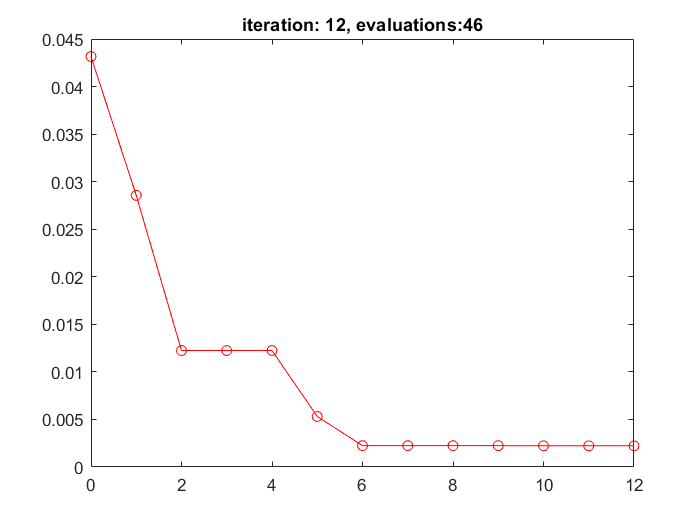

 iteration: 12, evaluation: 46, current best solution: 0.002228, real optimum: 0.000000
 iteration: 12, evaluation: 47, current best solution: 0.002228, difference: 0.000000
, samples: 18.000000
Refinement:1
Distance is 2.8273e-05


x =     0.9924    1.0100    0.7505


fval = 0.0022

results = struct with fields:
       initial: [30×4 double]
         min_x: [13×3 double]
         min_y: [0.0432 0.0286 0.0122 0.0122 0.0122 0.0053 0.0022 0.0022 0.0022 0.0022 0.0022 0.0022 0.0022]
       samples: [30 31 32 33 34 35 8 9 10 12 14 16]
             x: [18×3 double]
             y: [18×1 double]
    evaluation: 47
          fval: 0.0022
     iteration: 12
            EI: -1.4511e-04
          diff: 2.8273e-05
          flag: 0
    refinement: 1
         stall: 0


fun = @(x)frame_u_opti([ones(1,4) x],damaged(:,2:end),'mtmac'); % assign Branin function
num_vari = 3; % call number of variables
lwb = [.5 .5 .5]; upb = [1.01 1.01 1.01]; % search bounds
eps1 = 10^(-3); eps2 = 10^(-4); % stopping criterion 

[x,fval,results] = rEGO(fun,num_vari,lwb,upb,eps1,eps2)

#### References

[1] G. Dessena, D. I. Ignatyev, J. F. Whidborne, and L. Zanotti Fragonara, ‘A global-local meta-modelling technique for model updating’, [Accepted] Computer Methods in Applied Mechanics and Engineering, 2023.

[2] G. Dessena, D. I. Ignatyev, J. F. Whidborne, and L. Zanotti Fragonara, ‘A Kriging Approach to Model Updating for Damage Detection’, EWSHM 2022, Lecture Notes in Civil Engineering. Springer International Publishing, pp. 245–255, Jun. 16, 2022. (DOI: [10.1007/978-3-031-07258-1_26](https://doi.org/10.1007/978-3-031-07258-1_26)).

[3] G. Dessena, rEGO – A tutorial on the refined Efficient Global Optimisation, GitHub, Oct. 4, 2023. (DOI: [10.5281/zenodo.8406031](https://doi.org/10.5281/zenodo.8406031))

[4] A. Forrester, A. Sobester, A. Keane, A., Engineering design via surrogate modelling: a practical guide. Wiley. (DOI: [10.1002/9780470770801](https://doi.org/10.1002/9780470770801))

[5] E. Figueiredo, G. Park, J. Figueiras, C. Farrar, K. Worden, Structural health monitoring algorithm comparisons using standard data sets, Los Alamos National Laboratory (LANL), LA-14393 (DOI: [10.2172/961604](https://doi.org/10.2172/961604))